# **Desig af temperatur regulering**

clear all
close all 
clc
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



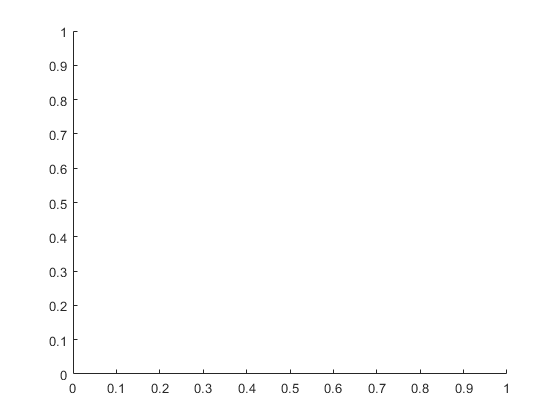

hold off

**Målt data (wostcase)**

load Step_Maaling_af_30_grader_tilsat_21_grader.txt

Ts_sensor = 17.76;
fs_sensor = 1/Ts_sensor

fs_sensor = 0.0563

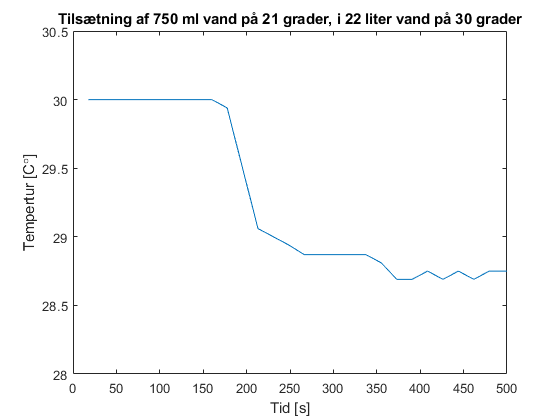


t_akse_koldt_vand = (1:length(Step_Maaling_af_30_grader_tilsat_21_grader))*(1/fs_sensor);

plot(t_akse_koldt_vand,Step_Maaling_af_30_grader_tilsat_21_grader)
title('Tilsætning af 750 ml vand på 21 grader, i 22 liter vand på 30 grader')
ylim([28 30.5])
xlim([0 500])
xlabel('Tid [s]')
ylabel('Tempertur [C{\circ}]')

**Målt data (Proces)**

load 'WaterHeated.mat'
step_respons_temp = WaterHeated_Fake(350:1419);
t_akse_step = (1:length(step_respons_temp))*(1/fs_sensor);
plot(t_akse_step,step_respons_temp)
hold on

**Åbensløjfe-krakterstik (Proces)**

offset = 22.3 %stuetemperatur

offset = 22.3000

input = 20 %procent duty cycle

input = 20

output = 25.19-offset %vand Temperatur

output = 2.8900

Type : 2 ordens

Zeta: 0.85

Settletime Tsettle  = 16000 s

wBW (båndbredde) = Wn (naturlige frekvens)

zeta = 0.85;
Tsettle = 16000

Tsettle = 16000

wBW=(4/(zeta*Tsettle))*sqrt((1-2*zeta^2)+sqrt(4*zeta^4-4*zeta^2+2)) 

wBW = 2.3704e-04

DC_gain=output/input

DC_gain = 0.1445


Gp=(DC_gain*(wBW^2))/(s^2+s*2*zeta*wBW+wBW^2)

Gp =
 
           8.119e-09
  ----------------------------
  s^2 + 0.000403 s + 5.619e-08
 
Continuous-time transfer function.



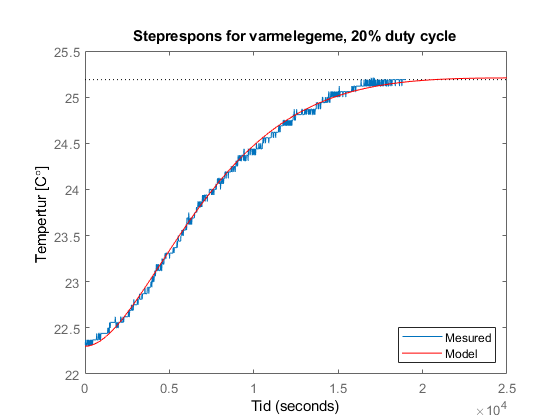


step(input*Gp+offset,'red')
legend('Mesured','Model','location','southeast')
title 'Steprespons for varmelegeme, 20% duty cycle'
ylabel('Tempertur [C{\circ}]')
xlabel('Tid')
ylim([22 25.5])
hold off

**Regulerings begrænsninger**

Systet er begrænset af en dytycycle fra 0 - 100%. Det vil sige systemte skal designet med mente at regulatorern ALDRIG vil forsøge at levere et output(dutycycle) til processen(Varmelegeme og vand) uden for begrændsningerne.

Worst case siturationen (Tilføjelse af 750 ml væske, af 21 grader, i 22 litter akvarievand af 30 grader) giver et temperaturfald på 1.2 grader.

Derfor defineres steppet systemet skal kunne håndtere.

**step = 1.2** *28.8 -> 30 grader*

**Grader offset = 28.8**

**Dutycycle offset = 45%**  *(28.8 grader i duty cycle)*

**Stationær fejl < 1%**

offset_28grader=28.8

offset_28grader = 28.8000

dutycycle_offset = (28.8-22.3)/0.1445

dutycycle_offset = 44.9827

Risetiem er pt uden regulering  = 11.000 sekunder

Vi designer efter et oversving på 10% og risetime på 8000 sekunder

heraf undersøges det om systmet er istand stil at udføre denne ændring i risetime, uden at gå i mætning, eller om en kortere risetime kan introduceres.

**OS = 10% -> Cmax = 1.1 -> Zeta 0.55 -> Fasemagen 60**

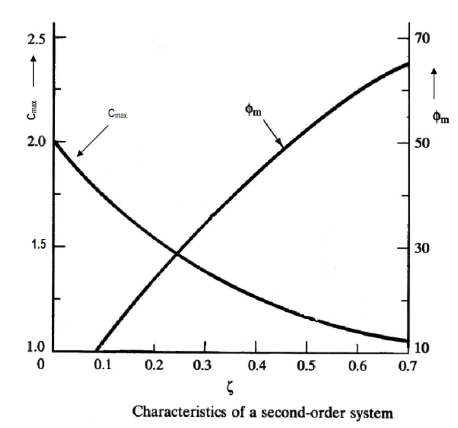

**fasemagenfrekvens**

Heraf findes en fasemagenfrekvesn der tilsvare zeta værdien på 0.55 og risetime på 8000

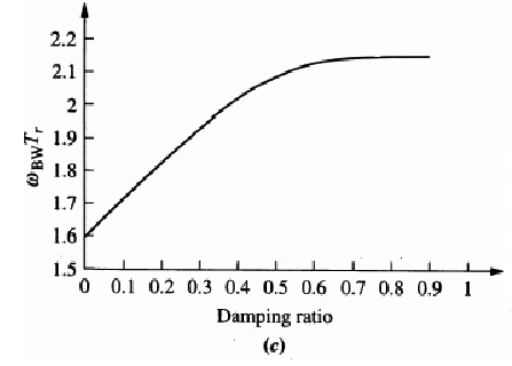

Wpm = 2.1/8000

Wpm = 2.6250e-04

**Lukketsløje karakterstik ved proportional led på 1 gg**

Kp = 1

Kp = 1

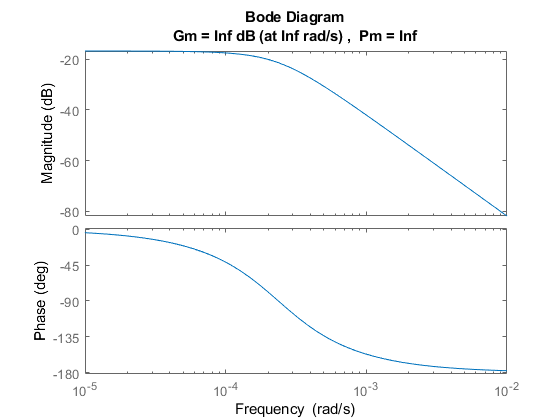

margin(Gp*Kp)

**Proportional kompensering**

Der introduceres et proportinal led, som hæver forstærkningen med 22.9 db for at få opnå en 0db knægfrekvens på fasemagenfrekvens (Wpm = 2.625*10^-4)

Kp = 10^(22.9/20)

Kp = 13.9637

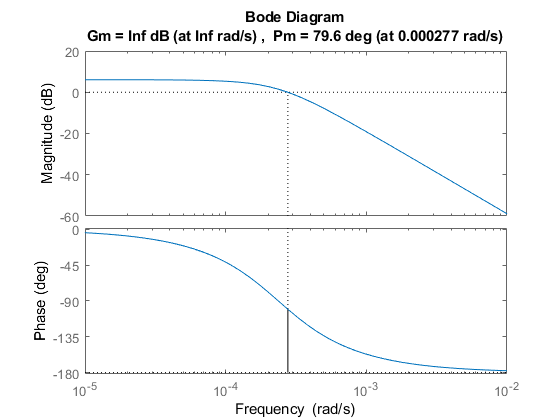

margin(Gp*Kp)

Tilføjelsen af Kp giver et stationær fejl på 33 procent.

DC_Gain = 10^(6.07/20)

DC_Gain = 2.0114

ess = 1/(1+DC_Gain)

ess = 0.3321

Procent dutycycle holdes øje med

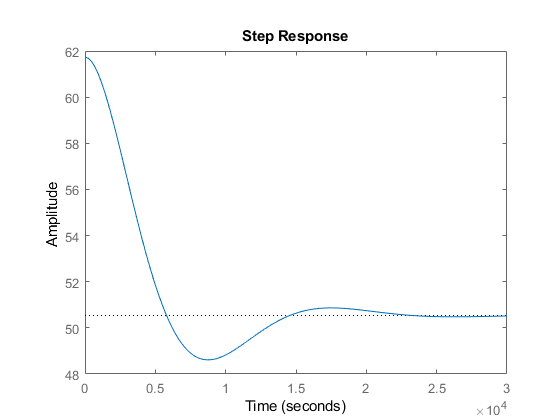

step(1.2*feedback(Kp,Gp)+dutycycle_offset)

Heraf kan det observeres at kun 62% af den maximale 100% dutycycle benyttes. 

Derfor hæves Kp således 100% dutycycle benyttes.

Kp = 10^(22.9/20)*3.3

Kp = 46.0802

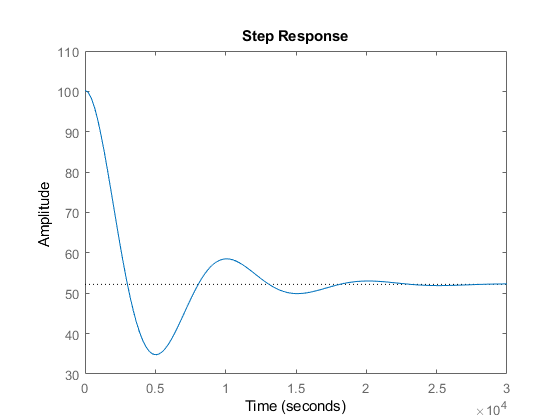

step(1.2*feedback(Kp,Gp)+dutycycle_offset)

Dette giver anledning til en fasemagenfrekvens på 5.88*10^-4

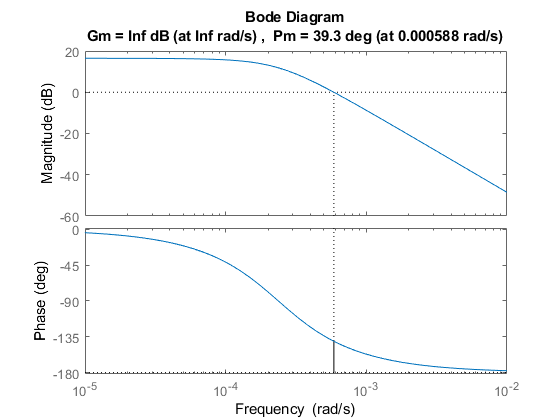

margin(Gp*Kp)

Wpm = 5.88*10^-4

Wpm = 5.8800e-04

Kp giver giver en mindre stationær fejl. ned til 13%

DC_Gain = 10^(16.46/20)

DC_Gain = 6.6527

ess = 100*(1/(1+DC_Gain))

ess = 13.0672

Kp kan ikke hæves mere, da de 100% dutycyle er opnået. Derfor tilføjes en Lag kompensering der kan sikre en stationærfejl på mindre end 1%

**Lag kompensering**

Tlag = 20/Wpm

Tlag = 3.4014e+04

Alpha = uendelig, således Lag kan konverteres til et "I" led i en PID model.

Glag = (s+(1/Tlag))/(s)

Glag =
 
  s + 2.94e-05
  ------------
       s
 
Continuous-time transfer function.



Ud fra bodeplottet af Lag kompenseringne kan de ses at fasenmagnen vil falde 2.9. Dette ses ikke som et problem pt

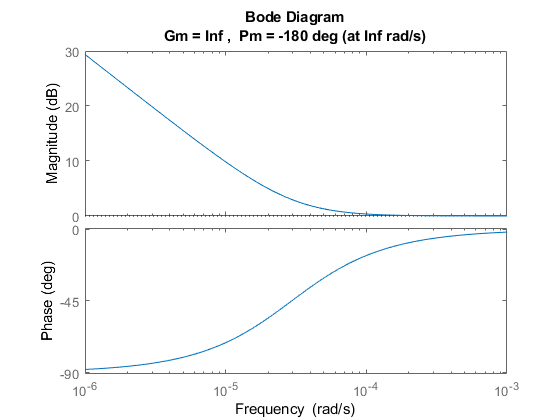

margin(Glag)

DC gain med Lag kompenseringne findes til 45.7 db

DC_Gain = 10^(45.7/20)

DC_Gain = 192.7525

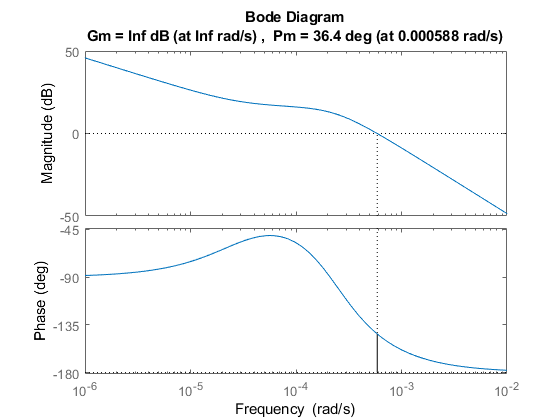

margin(Glag*Gp*Kp)

Lag regulatoreren ændre den stationære fejl ned til 0.51 procent!

100*(1/(1+DC_Gain))

ans = 0.5161

Dutycyclen befinder sig stadig i 0-100% området

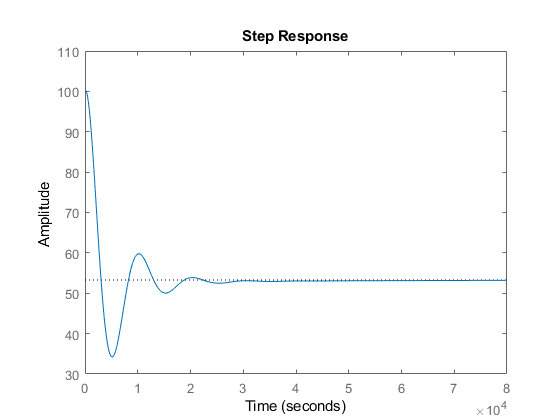

step(1.2*feedback(Glag*Kp,Gp)+dutycycle_offset)

**Steprespons for regulering og proces**

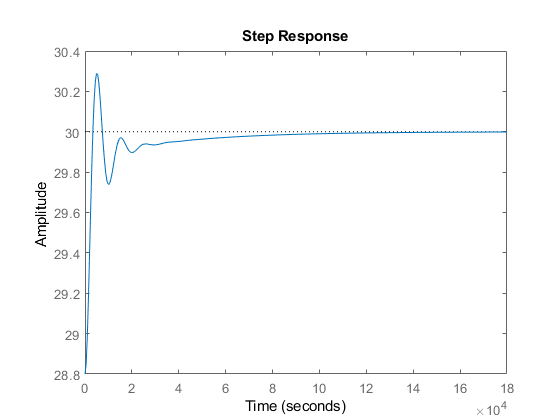

step(1.2*feedback(Glag*Kp*Gp,1)+offset_28grader)

S = stepinfo(1.2*feedback(Glag*Kp*Gp,1)+offset_28grader)

S = struct with fields:
        RiseTime: 2.2922e+03
    SettlingTime: 6.6068e+04
     SettlingMin: 29.7392
     SettlingMax: 30.2883
       Overshoot: 0.9610
      Undershoot: 0
            Peak: 30.2883
        PeakTime: 4.8886e+03


Her findes det hurtigste respons regulering kan udføre med dette benyttet varmelegeme.

Trise = 2292 sekunder

**konklusion**

- Der skal benyttes en anden taktik for tilføjelsen af væske til akvarie ved for lav vandstand. En taktik hvor vand tilføjes i mindre doser, så reguleringen kan følge med. 

- Der skal benyttes et større varmelegeme der hurtigere kan respondere på varmetabet. se fig (x) for sammenhængen mellem størrelse af varmelegeme med risetime. ()

**Valg**

- Vi fortsætter med varmeligemet på 120 watt og ændre tilføjelsen af væske.

Varmelegeme_watt = (60: 60: 6000);
Trise = zeros(1,length(Varmelegeme_watt))

Trise =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


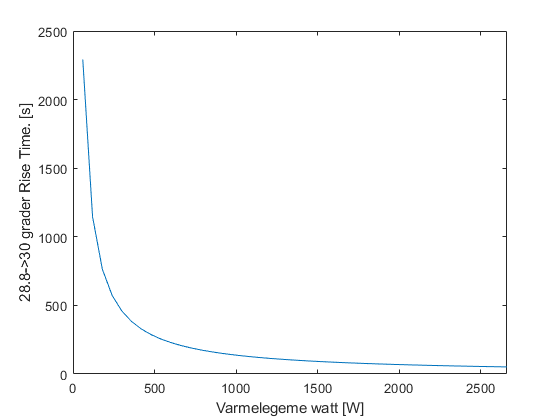


for n = 1:length(Varmelegeme_watt)
    Trise(n) = 2292/n;
end
plot(Varmelegeme_watt, Trise)
xlabel('Varmelegeme watt [W]')
ylabel('28.8->30 grader Rise Time. [s]')
xlim([0 2000])

Ref til forholdet mellem temperatur ændring, versus watt

https://bloglocation.com/art/water-heating-calculator-for-time-energy-power

**Diskretisering af regulering og sampling af proces**

Ved at sætte samplingtiden på 60 sekunder, er påvikrer fra diskretiseringen ubetydelig. Dette skyldes systemet er utroligt langsomt 

**Samplingtid = 60 sekunder**

Tsample=0.03528/Wpm

Tsample = 60

sampling frekven (radianer pr sek til svingning pr sek) 

fsample = (2*pi)*(1/Tsample)

fsample = 0.1047

sampling af proces

Gp_z = c2d(Gp,Tsample,'zoh');

Diskretisering af regulering

Gc_z=c2d(Glag*Kp,Tsample,'tustin');

Ændeing ved diskretisering

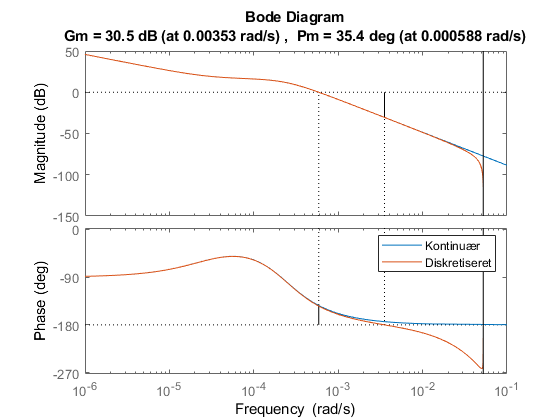

bode(Gp*Glag*Kp)
hold on
margin(Gp_z*Gc_z)
legend ('Kontinuær', 'Diskretiseret')
hold off

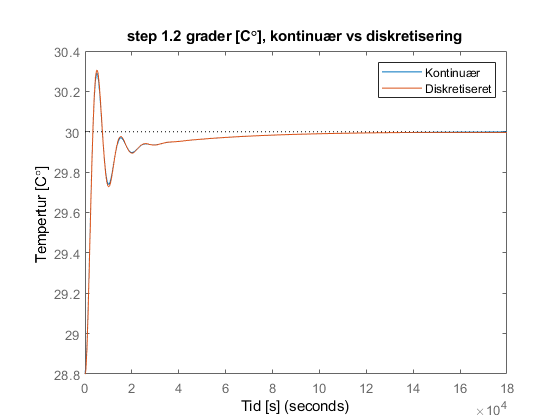


step(1.2*feedback(Gp*Glag*Kp,1)+offset_28grader)
hold on
step(1.2*feedback(Gp_z*Gc_z,1)+offset_28grader)
title 'step 1.2 grader [C{\circ}], kontinuær vs diskretisering'
xlabel('Tid [s]')
ylabel('Tempertur [C{\circ}]')
legend ('Kontinuær', 'Diskretiseret')
hold off

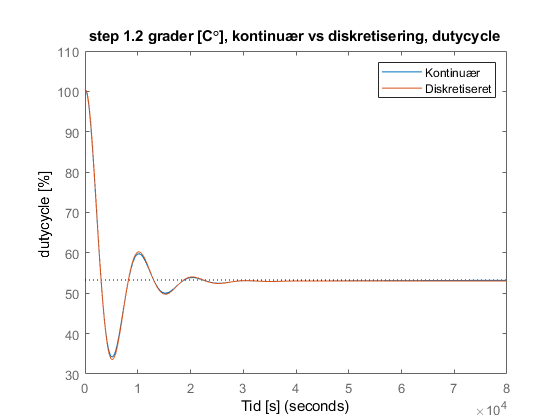

Kp_tuned = 34.0993

Gc_z =
 
  34.13 z - 34.07
  ---------------
       z - 1
 
Sample time: 60.034 seconds
Discrete-time transfer function.




step(1.2*feedback(Glag*Kp,Gp)+dutycycle_offset)
hold on
step(1.2*feedback(Gc_z,Gp_z)+dutycycle_offset)
title 'step 1.2 grader [C{\circ}], kontinuær vs diskretisering, dutycycle'
xlabel('Tid [s]')
ylabel('dutycycle [%]')
legend ('Kontinuær', 'Diskretiseret')
hold off

**Konvertingen fra Proportional-Lag regulator, til PI regulator**

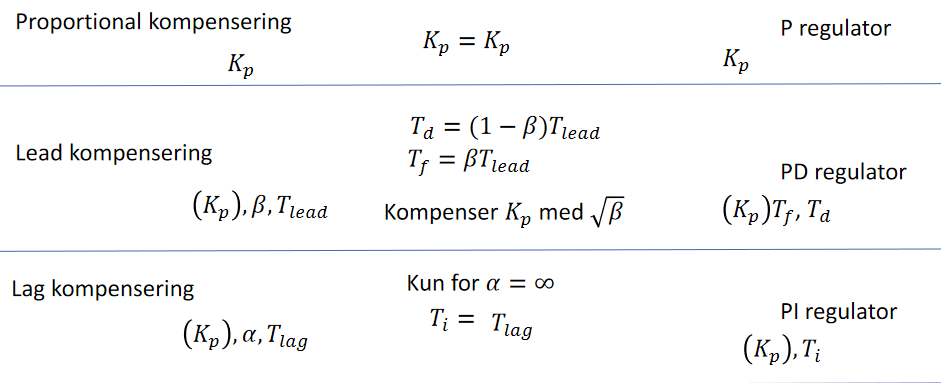

Ti = Tlag = 3.4014*10^-4

Kp = 46.0802

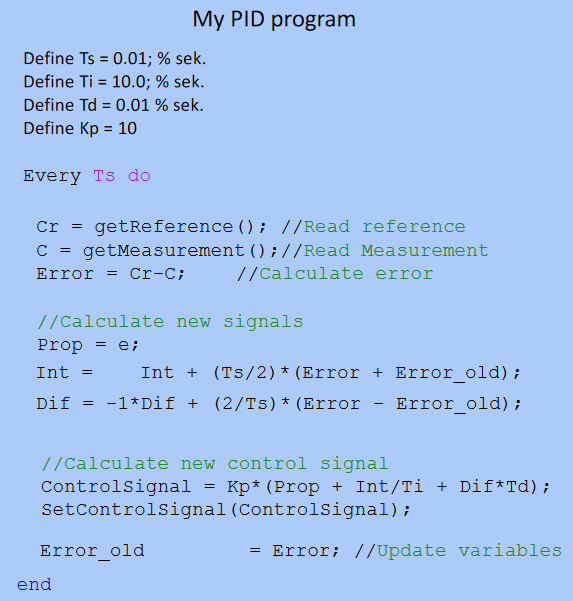

Definering af hvorfor integralledet ser sådan ud

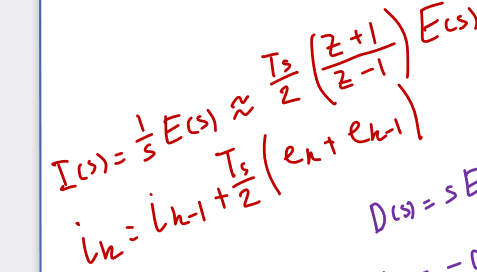

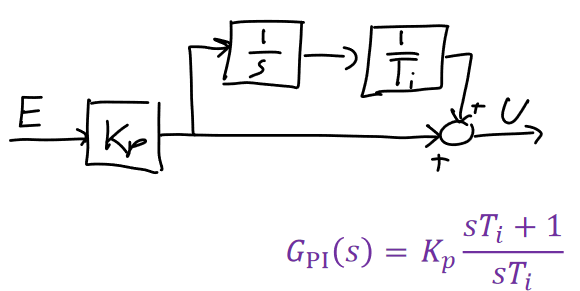

Rate limiter - rampe begrænser

25 -> 30

step 0.1 -> regulator

vent 10 min

25.1 -> 30

step 0.1 -> regulator

25.2 -> 30

vent 10 min ......

integrator logik, max 100% 

PI 

Opdater ikke integral, hvis control isgnal er under 100% (anti Winde up)